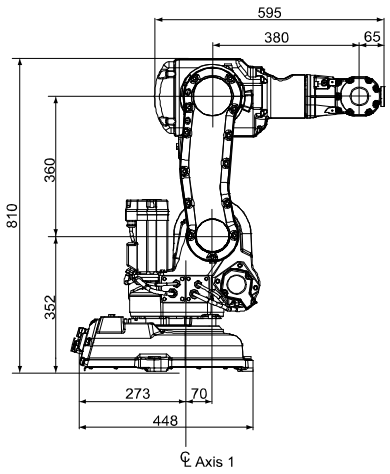

- Asigne los sistemas de referencia

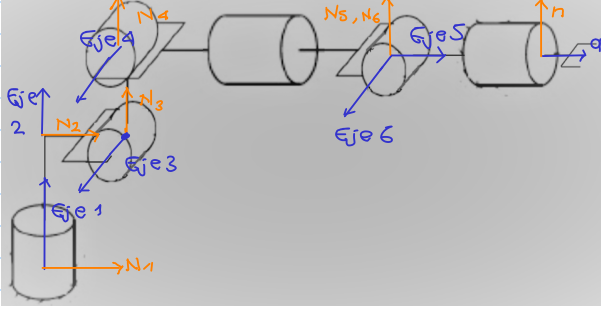

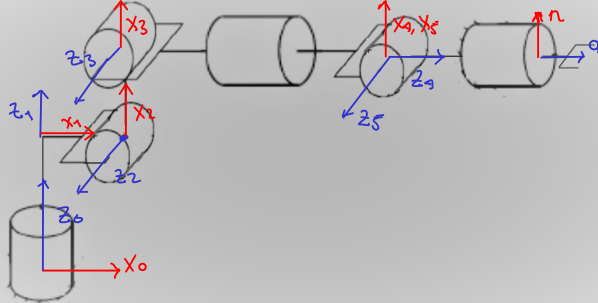

- Determine los parámetros DHmod

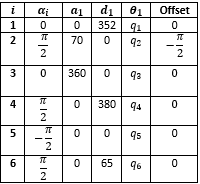

- Encuentre las MTH para cada eslabón.

clear all
syms q1 q2 q3 q4 q5 q6 pi 
T01=RevoluteMDH('alpha',0,'a',0,'d',352);
T12=RevoluteMDH('alpha',pi/2,'a',70,'d',0,'offset',-pi/2);
T23=RevoluteMDH('alpha',0,'a',360,'d',0);
T34=RevoluteMDH('alpha',pi/2,'a',0,'d',380);
T45=RevoluteMDH('alpha',-pi/2,'a',0,'d',0);
T5SYS=RevoluteMDH('alpha',pi/2,'a',0,'d',65);

T01.A(q1)

$$ans = \left(\begin{array}{cccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0 & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0 & 0\\ 0 & 0 & 1 & 352\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T12.A(q2)

$$ans = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{2} & \sigma_{1} & 0 & 70\\ -\cos\left(\frac{\pi }{2}\right)\,\sigma_{1} & \cos\left(\frac{\pi }{2}\right)\,\sigma_{2} & -\sin\left(\frac{\pi }{2}\right) & 0\\ -\sin\left(\frac{\pi }{2}\right)\,\sigma_{1} & \sin\left(\frac{\pi }{2}\right)\,\sigma_{2} & \cos\left(\frac{\pi }{2}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(\frac{\pi }{2}-q_{2}\right)\\ \sigma_{2}=\cos\left(\frac{\pi }{2}-q_{2}\right) \end{array}$$

T23.A(q3)

$$ans = \left(\begin{array}{cccc} \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & 0 & 360\\ \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T34.A(q4)

$$ans = \left(\begin{array}{cccc} \cos\left(q_{4}\right) & -\sin\left(q_{4}\right) & 0 & 0\\ \cos\left(\frac{\pi }{2}\right)\,\sin\left(q_{4}\right) & \cos\left(\frac{\pi }{2}\right)\,\cos\left(q_{4}\right) & -\sin\left(\frac{\pi }{2}\right) & -380\,\sin\left(\frac{\pi }{2}\right)\\ \sin\left(\frac{\pi }{2}\right)\,\sin\left(q_{4}\right) & \sin\left(\frac{\pi }{2}\right)\,\cos\left(q_{4}\right) & \cos\left(\frac{\pi }{2}\right) & 380\,\cos\left(\frac{\pi }{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T45.A(q5)

$$ans = \left(\begin{array}{cccc} \cos\left(q_{5}\right) & -\sin\left(q_{5}\right) & 0 & 0\\ \cos\left(\frac{\pi }{2}\right)\,\sin\left(q_{5}\right) & \cos\left(\frac{\pi }{2}\right)\,\cos\left(q_{5}\right) & \sin\left(\frac{\pi }{2}\right) & 0\\ -\sin\left(\frac{\pi }{2}\right)\,\sin\left(q_{5}\right) & -\sin\left(\frac{\pi }{2}\right)\,\cos\left(q_{5}\right) & \cos\left(\frac{\pi }{2}\right) & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T5SYS.A(0)

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(\frac{\pi }{2}\right) & -\sin\left(\frac{\pi }{2}\right) & -65\,\sin\left(\frac{\pi }{2}\right)\\ 0 & \sin\left(\frac{\pi }{2}\right) & \cos\left(\frac{\pi }{2}\right) & 65\,\cos\left(\frac{\pi }{2}\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

- Determine la formulación del modelo geométrico directo (cinemática directa).

T0SYS=T01.A(q1)*T12.A(q2)*T23.A(q3)*T34.A(q4)*T45.A(q5)*T5SYS.A(q6);
%Columna 1
T0SYS(:,1)

%Columna 2
T0SYS(:,2)

%Columna 3
T0SYS(:,3)

%Columna 4
T0SYS(:,4)

- Determine la posición y orientación del último sistema coordenado sabiendo que q = [ pi/3 pi/6 pi/18 pi/2 pi/6 3pi/2 ].

clear all
T01=RevoluteMDH('alpha',0,'a',0,'d',352);
T12=RevoluteMDH('alpha',pi/2,'a',70,'d',0,'offset',-pi/2);
T23=RevoluteMDH('alpha',0,'a',360,'d',0);
T34=RevoluteMDH('alpha',pi/2,'a',0,'d',380);
T45=RevoluteMDH('alpha',-pi/2,'a',0,'d',0);
T5SYS=RevoluteMDH('alpha',pi/2,'a',0,'d',65);
T0SYS=T01.A(pi/3)*T12.A(pi/6)*T23.A(pi/18)*T34.A(pi/2)*T45.A(pi/6)*T5SYS.A(3*pi/2);

- Para la configuración anterior exprese la posición en coordenadas cartesianas y la orientación en ángulos fijos. Contraste con RS

RPY=tr2rpy(T0SYS,'deg')

RPY =   124.0246    5.8144  -71.1522


Position=T0SYS(1:3,4)

Position =   -13.9636
  -89.1856
 -240.2120
